# Questão 4

Considerar as seguintes modulações:

- BPSK

- QPSK

- 8-PSK

- 16-QAM

- 64-QAM

**Critério de seleção**: maximização da eficiência espectral para um desempenho de probabilidade de erro limitante $P_e$.

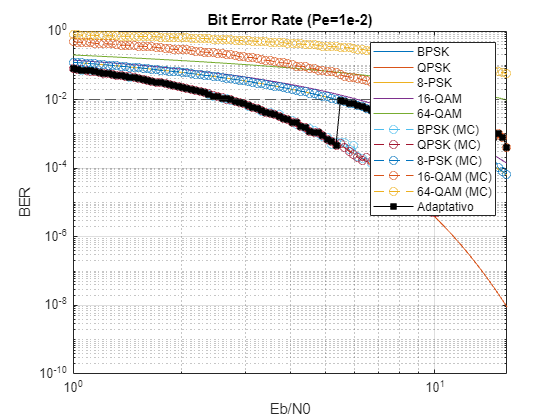

rng('default')

eb_n0 = logspace(0, 1.2, 100);

% Valores teóricos
bpsk_teorica = berawgn(pow2db(eb_n0), 'psk', 2, 'nondiff');
qpsk_teorica = berawgn(pow2db(eb_n0), 'psk', 4, 'nondiff');
psk8_teorica = berawgn(pow2db(eb_n0), 'psk', 8, 'nondiff');
qam16_teorica = berawgn(pow2db(eb_n0), 'qam', 16);
qam64_teorica = berawgn(pow2db(eb_n0), 'qam', 64);

% Valores simulados por Monte Carlo
bpsk_mc = m_psk(eb_n0, 2);
qpsk_mc = m_psk(eb_n0, 4);
psk8_mc = m_psk(eb_n0, 8);
qam16_mc = m_qam(eb_n0, 16);
qam64_mc = m_qam(eb_n0, 64);

% Valor do adaptativo usando cache pré-computado (opcional, apenas para melhor desempenho)
mcache(1,:) = qam64_mc;
mcache(2,:) = qam16_mc;
mcache(3,:) = psk8_mc;
mcache(4,:) = qpsk_mc;
mcache(5,:) = bpsk_mc;
pe_max = 1e-2;
adp = adaptativo(pe_max, eb_n0, mcache);


figure();
loglog(eb_n0, bpsk_teorica); hold on;
loglog(eb_n0, qpsk_teorica);
loglog(eb_n0, psk8_teorica);
loglog(eb_n0, qam16_teorica);
loglog(eb_n0, qam64_teorica);
loglog(eb_n0, bpsk_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qpsk_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, psk8_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qam16_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qam64_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, adp, 'k', 'LineStyle', '-', 'Marker', 'square', 'MarkerFaceColor', 'k');
yline(pe_max, 'LineStyle', '--');
hold off;
grid on;

title('Bit Error Rate (Pe=1e-2)');
xlabel('Eb/N0');
ylabel('BER');
legend('BPSK', 'QPSK', '8-PSK', '16-QAM', '64-QAM', ...
    'BPSK (MC)', 'QPSK (MC)', '8-PSK (MC)', '16-QAM (MC)', '64-QAM (MC)', 'Adaptativo');

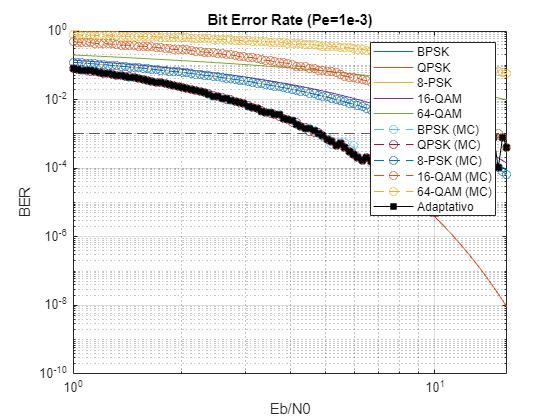

pe_max = 1e-3;
adp = adaptativo(pe_max, eb_n0, mcache);
figure();
loglog(eb_n0, bpsk_teorica); hold on;
loglog(eb_n0, qpsk_teorica);
loglog(eb_n0, psk8_teorica);
loglog(eb_n0, qam16_teorica);
loglog(eb_n0, qam64_teorica);
loglog(eb_n0, bpsk_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qpsk_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, psk8_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qam16_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, qam64_mc, 'LineStyle', '--', 'Marker', 'o');
loglog(eb_n0, adp, 'k', 'LineStyle', '-', 'Marker', 'square', 'MarkerFaceColor', 'k');
yline(pe_max, 'LineStyle', '--');
hold off;
grid on;

title('Bit Error Rate (Pe=1e-3)');
xlabel('Eb/N0');
ylabel('BER');
legend('BPSK', 'QPSK', '8-PSK', '16-QAM', '64-QAM', ...
    'BPSK (MC)', 'QPSK (MC)', '8-PSK (MC)', '16-QAM (MC)', '64-QAM (MC)', 'Adaptativo');